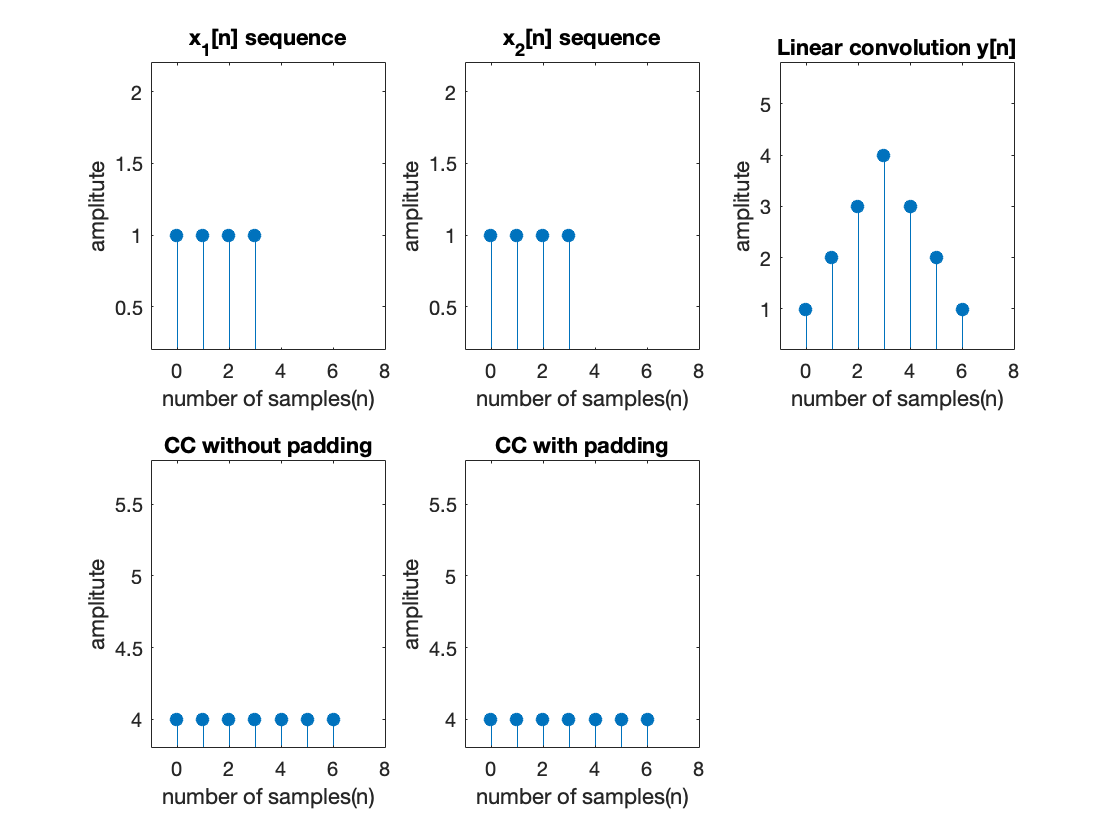

%----------------------------------------------------------------------
%Name : Sumit Patidar
%Roll no: B15237
%Task : program to compare linear and circular convolution
%----------------------------------------------------------------------

close all;
clc;

%take sequence as an input 
%I am assuming sequence starts from n = 1
x1 = input('enter the sequence x1: '); %example input = [1 2 3 4 5]
x2 = input('enter the sequence x2: ');
x1_length = length(x1);
x2_length = length(x2);
n_length = x1_length + x2_length - 1; %the size of convoluted signal which we will get
n1 = 0:1:x1_length - 1;
n2 = 0:1:x2_length - 1;
n = 0:1:n_length - 1;

%plot sequence x1
p1 = subplot(2,3,1);
stem(n1, x1, 'filled');
xlabel('number of samples(n)');
ylabel('amplitute');
title('x_1[n] sequence');
hold on;

%plot sequence x2
p2 = subplot(2,3,2);
stem(n2, x2, 'filled');
xlabel('number of samples(n)');
ylabel('amplitute');
title('x_2[n] sequence');
hold on;

%perform linear convolution
%{ y[i] = x_1[i]*x_2[i]
%       = sum (x_1[k]*x_2[i-k]), for each i in range [1, n_length]
%                              , k lies in range [1, x1_length]  i.e where x_1 is defined
%    Note: where x2 is not defined, it is taken as zero
%}

y = zeros(1,n_length);
for i = 0:n_length - 1
  for k = 0:x1_length - 1
        if ((i-k+1) <=0) || ((i-k+1) > x2_length)
            y(i+1) = y(i+1) + 0;
        else
            y(i+1) = y(i+1)  + x1(k+1)*x2(i-k+1);  %1 is added to indexing because matlab starts 
                                                   %array indexing from 1
        end
  end
end

%plot the convoluted sequence
p3 = subplot(2,3,3);
stem(n, y, 'filled');
xlabel('number of samples(n)');
ylabel('amplitute');
title('Linear convolution y[n]');
hold on;


%algorithm to perform circular convolution
%{ y[i] = x_1[i]*x_2[i]
%       = sum (x_1[k] * x_2[(i-k) mod (x2_length)]), for each i in range [1, n_length]
%                              , k lies in range [1, x1_length]  i.e where x_1 is defined
%    Note: where x2 is periodic in circular fashion 
%}

%compute circular convolution without padding zeros
y_circ_nozeros = zeros(1,n_length);
for i = 0:n_length - 1
  for k = 0:x1_length - 1
       j = mod(i-k, x2_length);
       y_circ_nozeros(i+1) = y_circ_nozeros(i+1)  + x1(k+1)*x2(j+1);  %1 is added to indexing because matlab starts 
                                                   %array indexing from 1
  end
end
%plot the circular convoluted sequence without padding zeros
p4 = subplot(2,3,4);
stem(n, y_circ_nozeros, 'filled');
xlabel('number of samples(n)');
ylabel('amplitute');
title('CC without padding');
hold on;

%perform circular convolution with given no of padded zeros
n_pad_zeros_x1 = input('Enter no of zeros to be padded for x1: '); %ask user for zeros to be padded
n_pad_zeros_x2 = input('Enter no of zeros to be padded for x2: ');

%pad zeros
x1_circ = [x1 zeros(1,n_pad_zeros_x1)];
x2_circ = [x2 zeros(1, n_pad_zeros_x2)];

%compute new array lengths
x1_circ_length = length(x1_circ);
x2_circ_length = length(x2_circ);
n_circ_length = x1_circ_length + x2_circ_length - 1; %the size of convoluted signal which we will get
n1_circ = 0:1:x1_circ_length - 1;
n2_circ = 0:1:x2_circ_length - 1;
n_circ = 0:1:n_circ_length - 1;

%compute circular convolution with padded zeros
y_circ = zeros(1,n_circ_length);
for i = 0:n_circ_length - 1
  for k = 0:x1_circ_length - 1
            j = mod(i-k, x2_circ_length);
            y_circ(i+1) = y_circ(i+1)  + x1_circ(k+1)*x2_circ(j+1);  %1 is added to indexing because matlab starts 
                                                   %array indexing from 1
  end
end

%plot the circular convoluted sequence
p5 = subplot(2,3,5);
stem(n_circ, y_circ, 'filled');
xlabel('number of samples(n)');
ylabel('amplitute');
title('CC with padding');
hold on;

%setting axis limits to visualize better
axis(p1, [-1  n_length+1 min(x1)*1.2-1 max(x1)*1.2+1]);
axis(p2, [-1  n_length+1 min(x2)*1.2-1 max(x2)*1.2+1]);
axis(p3, [-1  n_length+1 min(y)*1.2-1 max(y)*1.2+1]);
axis(p4, [-1  n_length+1 min(y_circ_nozeros)*1.2-1 max(y_circ_nozeros)*1.2+1]);
axis(p5, [-1  n_circ_length+1 min(y_circ)*1.2-1 max(y_circ)*1.2+1]);


display(n);

n =      0     1     2     3     4     5     6


display(y);

y =      1     2     3     4     3     2     1


display(y_circ_nozeros);

y_circ_nozeros =      4     4     4     4     4     4     4


display(y_circ);

y_circ =      4     4     4     4     4     4     4
